% getting all the individual datasets and cutting them to 1000

clear all;

clear gyro accel;

minsize = 1000;
[Accel1, ~] = parsePowerSenseData('AllisonStill1.csv');
[Accel2, ~] = parsePowerSenseData('AllisonStill2.csv');
[Accel3, ~] = parsePowerSenseData('AllisonStill3.csv');
[Accel4, ~] = parsePowerSenseData('AllisonStill4.csv');
[Accel5, ~] = parsePowerSenseData('AllisonStill5.csv');
[Accel6, ~] = parsePowerSenseData('AllisonStill6.csv');

[Accel7, ~] = parsePowerSenseData('AllisonMoving1.csv');
[Accel8, ~] = parsePowerSenseData('AllisonMoving2.csv');
[Accel9, ~] = parsePowerSenseData('AllisonMoving3.csv');
[Accel10, ~] = parsePowerSenseData('AllisonMoving4.csv');
[Accel11, ~] = parsePowerSenseData('AllisonMoving5.csv');
[Accel12, ~] = parsePowerSenseData('AllisonMoving6.csv');


% making all the lengths the same
axes = 4; %x, y, or z

%still
Accel1 = Accel1(1:minsize,axes);
Accel2 = Accel2(1:minsize,axes);
Accel3 = Accel3(1:minsize,axes);
Accel4 = Accel4(1:minsize,axes);
Accel5 = Accel5(1:minsize,axes);
Accel6 = Accel6(1:minsize,axes);

%walking
Accel7 = Accel7(1:minsize,axes);
Accel8 = Accel8(1:minsize,axes);
Accel9 = Accel9(1:minsize,axes);
Accel10 = Accel10(1:minsize,axes);
Accel11 = Accel11(1:minsize,axes);
Accel12 = Accel12(1:minsize,axes);



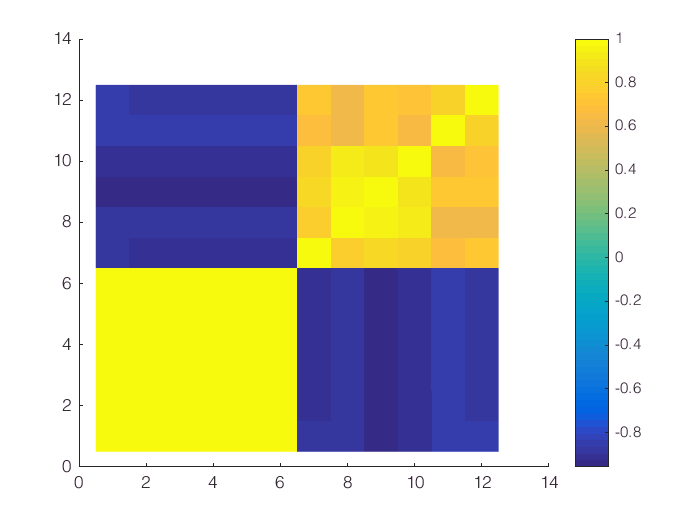

AllData = [Accel1,Accel2,Accel3,Accel4,Accel5,Accel6,Accel7,Accel8,Accel9,Accel10,Accel11,Accel12]';

% figure();
% hold on;
% plot(AllData(1,:), '-k');

% Fs = 1.2*length(Accel1); %what value is this?
Nx = 1000; 
% fx = linspace(-Fs/2, Fs/2 - Fs/Nx, Nx);

for k = 1:size(AllData,1)
    AllData(k,:)= filterData(AllData(k,:));
end

for q = 1:size(AllData,1)
    AllData(q,:) = abs(fft(AllData(q,:)/sqrt(Nx)));
end

figure
hold on;
TotalOrginalData = AllData;
AllData = mean_centered(AllData')';
imagesc(corr(AllData')); colorbar;

testingcorr = AllData;

%% fisherfaces

num = 6;

[U, S, Vi] = svd(AllData, 'econ');
principal_eigenvectors = Vi(:,1:num);

projection = (AllData * principal_eigenvectors)';

Sw = zeros(size(projection, 1), size(projection, 1));
Sb = zeros(size(projection, 1), size(projection, 1));

class_indices = [1 7];

for i = 1:size(class_indices, 2)
    class_begin = class_indices(i);
    if i == size(class_indices, 2)
        class_end = size(AllData, 1);
    else
        class_end = class_indices(i + 1) - 1;
    end
    classed_images = projection(:,class_begin:class_end);
    
    %finding the scatter matrix within classes
    mean_centered_classed_images = mean_centered(classed_images);
    Sw = Sw + mean_centered_classed_images*mean_centered_classed_images';
    %finding the scatter matrix between classes
    mean_centered_images = mean(projection, 2) - mean(classed_images, 2);
    Sb = Sb + size(classed_images, 2) * mean_centered_images * mean_centered_images';
end

[V, D] = eig(Sb, Sw);
[~, index] = sort(diag(D), 'descend');
V = V(:,index);

optimalW = principal_eigenvectors*V;

fishersleeping = AllData*optimalW;

[accelTEST, ~] = parsePowerSenseData('PravaStill.csv');

TEST = accelTEST(45:45+999, axes)';

TEST= filterData(TEST);

TEST = abs(fft(TEST/sqrt(Nx)));

total_data = [TotalOrginalData(1:12,:); TEST];

mean_centered_total_data = mean_centered(total_data')';

mean_centered_test = mean_centered_total_data(13,:);




testingcorr = [testingcorr(1:12,:); mean_centered_test];

size(testingcorr)

ans =           13        1000


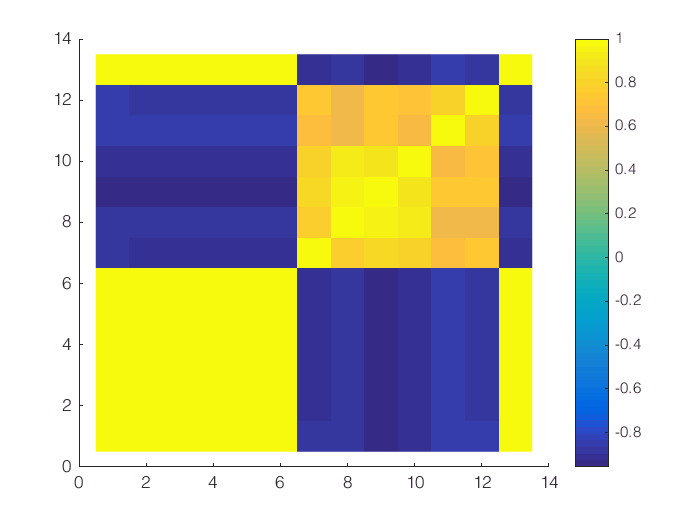


figure()
hold on;
imagesc(corr(testingcorr')); colorbar;


test_projection = mean_centered_test*optimalW;
test_duplicated = ones(size(fishersleeping,1),1)*test_projection;

diff = fishersleeping - test_duplicated;
dist = sum((diff.^2),2).^5;

minDis = min(dist);

index = find(dist==minDis,1);

isWalking = (index > 6);


determineWalking('longTestFinal.csv', 4, TotalOrginalData, optimalW, fishersleeping)

ans =      1     1     1     1     0     0     1     1     0     0     1     1     0


determineWalking('longmostlyrestFinal.csv', 4, TotalOrginalData, optimalW, fishersleeping)

ans =      0     0     0     0     1


**Functions**

function isWalking = determineWalking(fileName, axes, TotalOrginalData, optimalW, fishersleeping)
    
    
    
    Nx = 1000;
    windowSize = 1000;
    
    [accelTEST, ~] = parsePowerSenseData(fileName);

    numWindows = floor(size(accelTEST,1)/windowSize);
    
    indexHolder = zeros(1,numWindows);
    
    for o = 0:numWindows-1
        a = 1;
        b = 1000;
        TEST = accelTEST(a + o*1000: b + o*1000, axes)';
        TEST= filterData(TEST);
            
        TEST = abs(fft(TEST/sqrt(Nx)));
        
        total_data = [TotalOrginalData(1:12,:); TEST];
        
        mean_centered_total_data = mean_centered(total_data')';
        
        mean_centered_test = mean_centered_total_data(13,:);
        test_projection = mean_centered_test*optimalW;
        test_duplicated = ones(size(fishersleeping,1),1)*test_projection;
        
        diff = fishersleeping - test_duplicated;
        dist = sum((diff.^2),2).^5;
        
        minDis = min(dist);
        
        index = find(dist==minDis,1);
        
        isWalkingSingle = (index > 6);
        
        indexHolder(o+1) = isWalkingSingle;
    end
    
    isWalking = indexHolder;
            
%     testingcorr = [testingcorr(1:12,:); mean_centered_test];
%     
%     size(testingcorr)
%         
%     figure()
%     hold on;
%     imagesc(corr(testingcorr')); colorbar;
end



function mean_centered_data = mean_centered(reshaped_image)
    o = ones(1,size(reshaped_image,2));
    m = mean(reshaped_image,2)*o;
    mean_centered_data = reshaped_image-m;
end

function [out] = UnitSig(X)
    if(X == 0)
        out = 1;
    else
        out = 0;
    end
end

function ans2 = filterData(data)
    Fs = 1.2*length(data); %what value is this?
    Nx = length(data); 
    fx = linspace(-Fs/2, Fs/2 - Fs/Nx, Nx);
    
    Fs = 49.77;
    
    n = [-42:41];
    %wc = 4*pi/Fs;
    wc = 8*pi/Fs;
    h = wc/pi*sinc(wc*n/pi);
   
    
    ans1 = conv(data, h, 'same');
    
    wc = pi/500;
    holdvec = zeros(length(n),1);
    for i= 1:length(n)
        t = n(i);
        holdvec(i) = UnitSig(t)- wc/pi * sinc(wc*t/pi) ;
    end
    ans2 = conv(ans1, holdvec, 'same');
end